# 1 SYSTEM MODEL AND GENERATION OF BIT SEQUENCE AND QAM SYMBOLS

### 1.1 SYSTEM MODEL

## 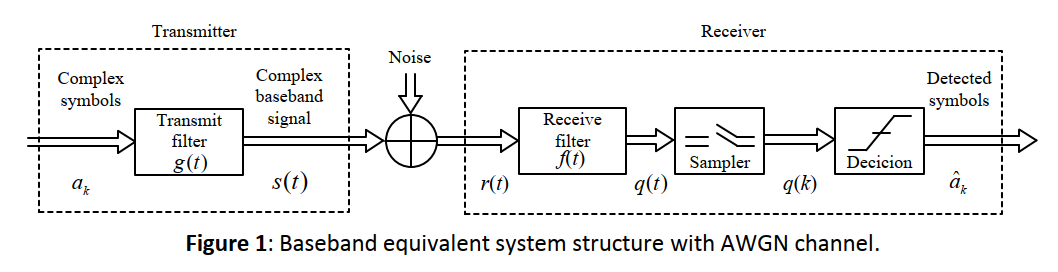

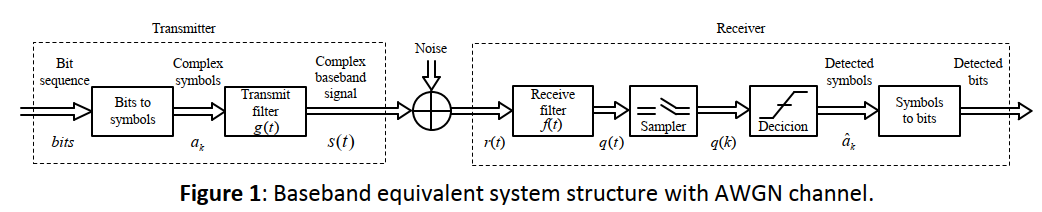

## 1.2 CONSIDERED SYSTEM PARAMETERS

close all
clear all
clc

SNR = 0:2:24; % Signal-to-noise ratio vector [dB] % ------CHANGE------
T = 1/40e6; % Symbol time interval [s]
r = 3; % Oversampling factor (r samples per pulse)
N_symbols_per_pulse = 16; % Duration of TX/RX filter in symbols
alpha = 0.20; % Roll-off factor (excess bandwidth)

Fs = r/T;               % Sampling frequency 
Ts = 1/Fs;              % Sampling time interval 

### 1.3 GENERATION OF QAM SYMBOLS

N_symbols = 1000;      % Number of symbols 

% Alphabet size 
M = 16; %-------------------CHANGE---------------- 
% Number of symbols in the QAM alphabet (e.g. 16 means 16-QAM).  
% Valid alphabet sizes are 4, 16, 64, 256, 1024, ...  
% (i.e. the possible values are given by the vector 2.^(2:2:N), for any N) 
  
% Here qam_axis presents the symbol values in real/imaginary axis.  
% So, generally for different alphabet/constellation sizes (): 
qam_axis = -sqrt(M)+1:2:sqrt(M)-1; 
% For example, the above results in 
% qam_axis = [-1 1];                % for QPSK 
% qam_axis = [-3 -1 1 3];           % for 16-QAM 
% qam_axis = [-7 -5 -3 -1 1 3 5 7]; % for 64-QAM 
  
% generation of a complex constellation: 
alphabet = bsxfun(@plus,qam_axis',1j*qam_axis); %help bsxfun 
% equivalent to alphabet = repmat(qam_axis', 1, sqrt(alphabet_size)) + ... 
%                          repmat(1j*qam_axis, sqrt(alphabet_size), 1);  
alphabet = alphabet(:).'; % alphabet symbols as a row vector 
  
% Scaling the constellation, so that the mean power of a transmitted symbol 
% is one (e.g., with QPSK this is 1/sqrt(2), and for 16-QAM 1/sqrt(10)) 
alphabet_scaling_factor = 1/sqrt(mean(abs(alphabet).^2)); 
alphabet = alphabet*alphabet_scaling_factor; 
   
%%%%%% Random vector of symbol indices (i.e., numbers between 1...alphabet_size) %
%symbol_ind = randi(length(alphabet),1,N_symbols);    
  
%symbols = alphabet(symbol_ind); % Symbols to be transmitted 
  
% Plot the symbols 
%figure 
%plot(symbols,'ro', 'MarkerFaceColor','r') 
%axis equal 
%xlabel('Re') 
%ylabel('Im') 
%title('Transmitted symbols')


%Generate Randm Bit sequence ---------------CHANGE--------------
% Number of bits, defined for a fixed alphabet size and number of symbols 
N_bits = log2(M)*N_symbols; 
  
% Random bit sequence 
bits = randi(2,N_bits,1)-1;

%Reshape bits to symbols  ---------------CHANGE--------------
% Block of bits in the columns 
B = reshape(bits,log2(M),[]);

% Powers of two: ..., 2^3, 2^2, 2^1, 2^0 
q = 2.^(log2(M)-1:-1:0);  
  
% Symbol indices between 0...M-1, i.e. bit blocks to decimal numbers 
symbol_indices = q*B;

%GRAY Coding -------------------------CHANGE------------------------------ 
% Gray coded symbol indices. This is basically an operation where the 
% symbol indices are mapped to Gray-coded symbol indices. Another option 
% would be reordering the original symbol alphabet, but the overall effects  
% would be exactly the same.  
[Gray_symbol_indices, ~] = bin2gray(symbol_indices, 'qam', M); 

  
% Symbols from the alphabet, based on the Gray-coded symbol indices above. 
% Note that we need to add 1 to the indices since the indexing must be 
% between 1...M (the addition is later removed in the RX). 
symbols = alphabet(Gray_symbol_indices+1);

## 2 TRANSMITTER STRUCTURE

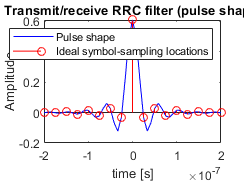

% Filter generation 
gt = rcosdesign(alpha,N_symbols_per_pulse,r,'sqrt');
% Plot the pulse shape of the transmit/receive filter 
figure 
plot(-N_symbols_per_pulse*r/2*Ts:Ts:N_symbols_per_pulse*r/2*Ts,gt,'b') 
hold on 
stem(-N_symbols_per_pulse*r/2*Ts:T:N_symbols_per_pulse*r/2*Ts,gt(1:r:end),'ro') 
xlabel('time [s]') 
ylabel('Amplitude') 
title('Transmit/receive RRC filter (pulse shape)') 
legend('Pulse shape','Ideal symbol-sampling locations')

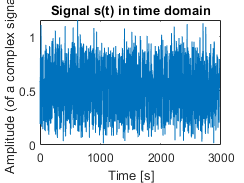


% Zero vector initilized for up-sampled symbol sequence 
symbols_upsampled = zeros(size(1:r*N_symbols));     
  
% symbol insertion 
symbols_upsampled(1:r: r*N_symbols) = symbols; 
% now the up-sampled sequence looks like {a1 0 0... a2 0 0... a3 0 0...} 
  
st = filter(gt,1,symbols_upsampled); % Transmitter filtering 
st = st(1+(length(gt)-1)/2:end);     % Filter delay correction

figure % zoom manually to see the signal better 
plot(abs(st)) 
xlabel('Time [s]') 
ylabel('Amplitude (of a complex signal)') 
title('Signal s(t) in time domain') 

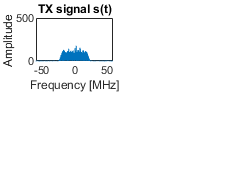

  
NFFT = 2^14;                            %FFT size 
f = -Fs/2:1/(NFFT*Ts):Fs/2-1/(NFFT*Ts); %frequency vector 
  
% Plot the transmit signal in frequency domain 
figure(4) 
subplot(2,2,1); 
plot(f/1e6, fftshift(abs(fft(st, NFFT)))); 
xlabel('Frequency [MHz]') 
ylabel('Amplitude ') 
title('TX signal s(t)') 
ylim([0 500]);

## 3 CHANNEL MODEL 

% Complex white Gaussian random noise 
n = (1/sqrt(2))*(randn(size(st)) + 1j*randn(size(st))); 
  
P_s = var(st);              % Signal power 
P_n = var(n);               % Noise power            
  
% Defining noise scaling factor based on the desired SNR: 
noise_scaling_factor = sqrt(P_s/P_n./10.^(SNR./10)*(r/(1+alpha)));

% Initialization for RX signal matrix, where each row represents the 
% received signal with a specific SNR value 
rt = zeros(length(SNR), length(st)); 
  
% Received signal with different SNR values 
for ii = 1:1:length(SNR) 
    rt(ii,:) = st + noise_scaling_factor(ii)*n; 
end

% Plot the amplitude response of the noise with the SNR corresponding  
% to the last value in the SNR vector (just as an example) 
figure(4) 
subplot(2,2,2) 
plot(f/1e6, fftshift(abs(fft(noise_scaling_factor(end)*n, NFFT)))); 
xlabel('Frequency [MHz]') 
ylabel('Amplitude') 
title(['Noise (corresponding to SNR = ', num2str(SNR(end)), ' dB)']) 
ylim([0 500]); 
  
% Received signal with the noise when the SNR is equal to the last value of 
% the SNR vector 
figure(4) 
subplot(2,2,3) 
plot(f/1e6, fftshift(abs(fft(rt(end,:), NFFT)))); 
xlabel('Frequency [MHz]') 
ylabel('Amplitude') 
title(['RX signal r(t) (SNR = ', num2str(SNR(end)), ' dB)']) 
ylim([0 500]);

## 4 RECEIVER STRUCTURE

### 4.1 SIGNAL FILTERING AND SAMPLING

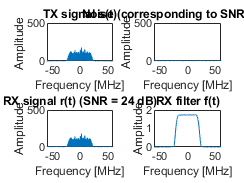

% Creating the receive filter (it is the same as in the transmitter) 
ft = gt; 
  
% Plotting the amplitude response of the receive filter 
figure(4) 
subplot(2,2,4) 
plot(f/1e6, fftshift(abs(fft(ft, NFFT)))); 
xlabel('Frequency [MHz]') 
ylabel('Amplitude') 
title('RX filter f(t)') 

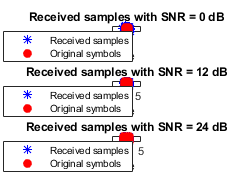

  
% Initialization for the received symbol matrix, where each row represents 
% the symbols with a specific SNR value

qk = zeros(length(SNR), N_symbols - N_symbols_per_pulse); 
% Note that due to filtering transitions, we loose some of the last 
% symbols of the symbol sequence. In practice we would simply continue  
% taking a few samples after the sequence to try to get all the symbols.  
% However, filter transitions in the beginning and in end are always  
% creating non-idealities to the transmission (the same is also happening  
% in frequency domain: e.g. compare data in the middle and in the edge of 
% the used band). 
  
% Filtering and sampling 
for ii = 1:1:length(SNR) 
    qt = filter(ft,1,rt(ii,:));      % Receiver filtering  
    qt = qt(1+(length(ft)-1)/2:end); % Filter delay correction 
     
    % Sampling the filtered signal. Remember that we used oversampling in 
    % the TX. 
    qk(ii,:) = qt(1:r:end); 
end

% Plot a few examples of the noisy samples and compare them with the 
% original symbol alphabet 
figure(5) 
subplot(3,1,1) 
plot(qk(1,:),'b*') 
hold on 
plot(alphabet,'ro', 'MarkerFaceColor','r') 
hold off 
legend('Received samples', 'Original symbols') 
xlabel('Re') 
ylabel('Im') 
title(['Received samples with SNR = ', num2str(SNR(1)), ' dB']) 
axis equal 
  
figure(5) 
subplot(3,1,2) 
mid_ind = ceil(length(SNR)/2);  % index for the entry in the middle 
plot(qk(mid_ind,:),'b*') 
hold on 
plot(alphabet,'ro', 'MarkerFaceColor','r') 
hold off 
legend('Received samples ', 'Original symbols') 
xlabel('Re') 
ylabel('Im') 
title(['Received samples with SNR = ', num2str(SNR(mid_ind)), ' dB']) 
axis equal 
  
figure(5) 
subplot(3,1,3) 
plot(qk(end, :),'b*') 
hold on 
plot(alphabet,'ro', 'MarkerFaceColor','r') 
hold off 
legend('Received samples ', 'Original symbols') 
xlabel('Re') 
ylabel('Im') 
title(['Received samples with SNR = ', num2str(SNR(end)), ' dB']) 
axis equal 

### 4.2 OBTAINING SYMBOL DECISIONS AND CALCULATING THE SYMBOL ERROR RATE (SER)

% Initialization 
BER = zeros(1,length(SNR)); 
  
for ii = 1:1:length(SNR) 
  
    alphabet_error_matrix = abs(bsxfun(@minus,alphabet.',qk(ii,:))); 
    % Now, rows represent the alphabet symbol indices and columns represent  
    % the received symbol indices (e.g. the Euclidian distance between the  
    % 5th received symbol and the 3rd symbol in the alphabet is given as 
    % "alphabet_error_matrix(3,5)" 
     
    % Searching for the indeces corresponding to the minimum distances
    % ----------------CHANGE ------------- Name of function
    [~,estimated_Gray_symbol_ind] = min(alphabet_error_matrix); 
    
    % Decoding the Gray-coded symbol indices. Remember that we added 1 to 
    % the Gray-coded symbol indices in the TX, so now its effects 
    % need to be removed by substracting 1 from the estimated Gray coded 
    % symbol indeces.  
    
    estimated_symbol_indices = ... 
        gray2bin(estimated_Gray_symbol_ind-1,'qam',M); 

    % block of estimated bits in the columns --------CHANGE------
    estimated_bit_blocks = ... 
        rem(floor((estimated_symbol_indices(:))*2.^(1-log2(M):0)),2)'; 
    % remember again that we have to remove one from the estimated symbol 
    % indices ("estimated_symbol_ind(:)-1") in order to get numbers to start 
    % from zero value
     
    
    %symbol_errors = ... 
    %    estimated_symbol_ind ~= symbol_ind(1:length(estimated_symbol_ind)); 
         
    % Symbol error rate (0 means 0% of errors, 1 means 100% of errors) 
    %SER(1,ii) = mean(symbol_errors); 


    % Bit blocks to bit vector 
    estimated_bits = estimated_bit_blocks(:); 
     
    % Finding out which bits were estimated incorrecly: 
    bit_errors = ... 
        estimated_bits ~= bits(1:length(estimated_bits)); 
         
    % Bit error rate (0 means 0% of errors, 1 means 100% of errors) 
    BER(1,ii) = mean(bit_errors); 
  
end 

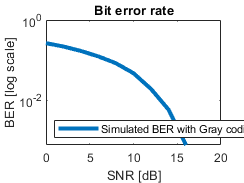

  
% Based on the lecture slides on p. 156, an approximation for the BER can 
% be given as BER = 1/log2(M) * symbol_error_probability, assuming Gray 
% coding where the nearest neigbors differ only one bit.  


% Find out the minimum distance between two constellation points 
d = min(abs(alphabet(1)-alphabet(2:end))); 
  
% Sigma values. Note that we need to first divide the original power of the 
% noise by two in order to get the parameter used in the equations. 
% Variable noise_scaling_factor was used for amplitudes so we need to 
% square it for getting the corresponding power scaling factor.  
sigma = sqrt(0.5 * P_n * noise_scaling_factor.^2); 
  
% Theoretical symbol error probability  applicable to all M-QAM alphabets.
P_sym_error = (4*qfunc(d./(2*sigma)) - 4*qfunc(d./(2*sigma)).^2) ... 
    * ((M-4-4*(sqrt(M)-2))/M) + ... 
    (2*qfunc(d./(2*sigma))- qfunc(d./(2*sigma)).^2) * (4/M) + ... 
    (3*qfunc(d./(2*sigma)) - 2*qfunc(d./(2*sigma)).^2) * (4*(sqrt(M)-2)/M); 


% Note that we could calculate this for 16-QAM directly as in p. 151: 
% P_sym_error_16QAM = 3*qfunc(d./(2*sigma)) - 2.25*qfunc(d./(2*sigma)).^2; 
% but now the probability is given in a more generic form and thus is  
% applicable to all M-QAM alphabets. 
  
% Compare the simulated and theoretical results. ------CHANGE--------
% You can also check lecture slides p. 161 for more examples. 
figure 
semilogy(SNR, BER, 'LineWidth', 3); 
hold on; 
%semilogy(SNR, (1/log2(M))*P_sym_error, 'r--', 'LineWidth', 2); 
title('Bit error rate') 
xlabel('SNR [dB]') 
ylabel('BER [log scale]') 
legend('Simulated BER with Gray coding',... 
    'Theoretical bit error probability (approx.)','Location', 'SouthWest'); 